# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 26-Nov-2024 19:18:46

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 14);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Time", "LE", "F4", "C4", "P4", "P3", "C3", "F3", "Trigger", "Time_Offset", "ADC_Status", "ADC_Sequence", "Event", "Comments"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "char"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Comments", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Comments", "EmptyFieldRule", "auto");

% Import the data
WFR5 = readtable("/Users/gayatrimalladi/Desktop/untitled folder/Prof_Mat_pre_stroke/WFR5.txt", opts)

WFR5 = 18843×14 table
     Time      LE        F4         C4       P4       P3       C3       F3      Trigger    Time_Offset    ADC_Status    ADC_Sequence    Event      Comments  
    ______    _____    _______    ______    _____    _____    _____    _____    _______    ___________    __________    ____________    _____    ____________

       NaN      NaN        NaN       NaN      NaN      NaN      NaN      NaN      NaN          NaN           NaN            NaN          NaN     {'Comments'}
    0.0033    -85.8      33

## Clear temporary variables

clear opts
clear opts
% Extract EEG channels
eeg_channels = WFR5{:, ["LE", "F4", "C4", "P4", "P3", "C3", "F3"]};

% Check for NaN or Inf in the EEG channels
if any(~isfinite(eeg_channels(:)))
    eeg_channels(~isfinite(eeg_channels)) = 0; % Replace non-finite values with zeros
end

% Define sampling frequency and channel names
sfreq = 300; % Sampling frequency in Hz
ch_names = {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}; % Channel names

% Apply notch filter to remove powerline noise
notch_freqs = [50, 60]; % Frequencies to remove
for i = 1:length(notch_freqs)
    d = designfilt('bandstopiir', 'FilterOrder', 2, ...
        'HalfPowerFrequency1', notch_freqs(i) - 1, ...
        'HalfPowerFrequency2', notch_freqs(i) + 1, ...
        'SampleRate', sfreq);
    eeg_channels = filtfilt(d, eeg_channels); % Apply filter
end

% Define bandpass filter parameters
low_freq = 7;  % Lower cutoff frequency (Hz)
high_freq = 14; % Upper cutoff frequency (Hz)

% Design a bandpass filter
[b, a] = butter(4, [low_freq high_freq] / (sfreq / 2), 'bandpass');

% Apply the bandpass filter to the EEG data
filtered_data = filtfilt(b, a, eeg_channels);

% Display a summary of the filtered data
disp('Filtered EEG data:');

Filtered EEG data:


disp(filtered_data);

    1.0369   -1.5126    0.2204    0.9673    0.8028   -0.0640    0.7753
   46.9191 -163.2947  -13.9005   42.5194   25.8768   -2.8040   20.0481
   90.3969 -316.5464  -27.2447   81.8964   49.6517   -5.3611   38.3180
  129.3169 -453.6528  -39.1286  117.1550   70.9712   -7.5964   54.6966
  161.7947 -567.9601  -48.9582  146.5946   88.8214   -9.3933   68.4048
  186.3228 -654.1573  -56.2651  168.8548  102.3881  -10.6650   78.8166
  201.8523 -708.5670  -60.7323  182.9888  111.1004  -11.3598   85.4925
  207.8450 -729.3282  -62.2105  188.5102  114.6581  -11.4633   88.2010
  204.2919 -716.4592  -60.7233  185.4094  113.0426  -10.9986   86.9262
  191.6982 -671.8011  -56.4604  174.1399  106.5087  -10.0234   81.8627
  171.0361 -598.8471  -49.7607  155.5758   95.5610   -8.6245   73.3974
  143.6707 -502.4746  -41.0859  130.9453   80.9154   -6.9104   62.0800
  111.2642 -388.6004  -30.9875  101.7435   63.4486   -5.0031   48.5851
   75.6650 -263.7848  -20.0689   69.6335   44.1413   -3.0284   33.6679
   38.


% Compute statistics
stats.mean = mean(eeg_channels, 1); % Mean
stats.variance = var(eeg_channels, 0, 1); % Variance
stats.std_dev = std(eeg_channels, 0, 1); % Standard Deviation
stats.median = median(eeg_channels, 1); % Median
stats.min = min(eeg_channels, [], 1); % Minimum
stats.max = max(eeg_channels, [], 1); % Maximum

% Display statistics
disp('Statistics for EEG Channels:');

Statistics for EEG Channels:


disp(array2table([stats.mean; stats.variance; stats.std_dev; stats.median; stats.min; stats.max], ...
    'VariableNames', ["LE", "F4", "C4", "P4", "P3", "C3", "F3"], ...
    'RowNames', {'Mean', 'Variance', 'StdDev', 'Median', 'Min', 'Max'}));

                   LE         F4          C4          P4         P3         C3          F3   
                ________    _______    ________    ________    _______    _______    ________

    Mean         0.84911    -2.3628    -0.50758     0.59903    0.45049    0.78123    -0.46855
    Variance      391.63     4747.4      150.19      305.92     189.05     70.731         236
    StdDev         19.79     68.902      12.255      17.491     13.749     8.4102      15.362
    Median      -0.25053     4.2015     0.28147    -0.37118    -0.7646    0.67286      0.5581
    Min          -54.685    -1891.7     -171.36     -50.868    -32.758    -44.811     -87.471
    Max   

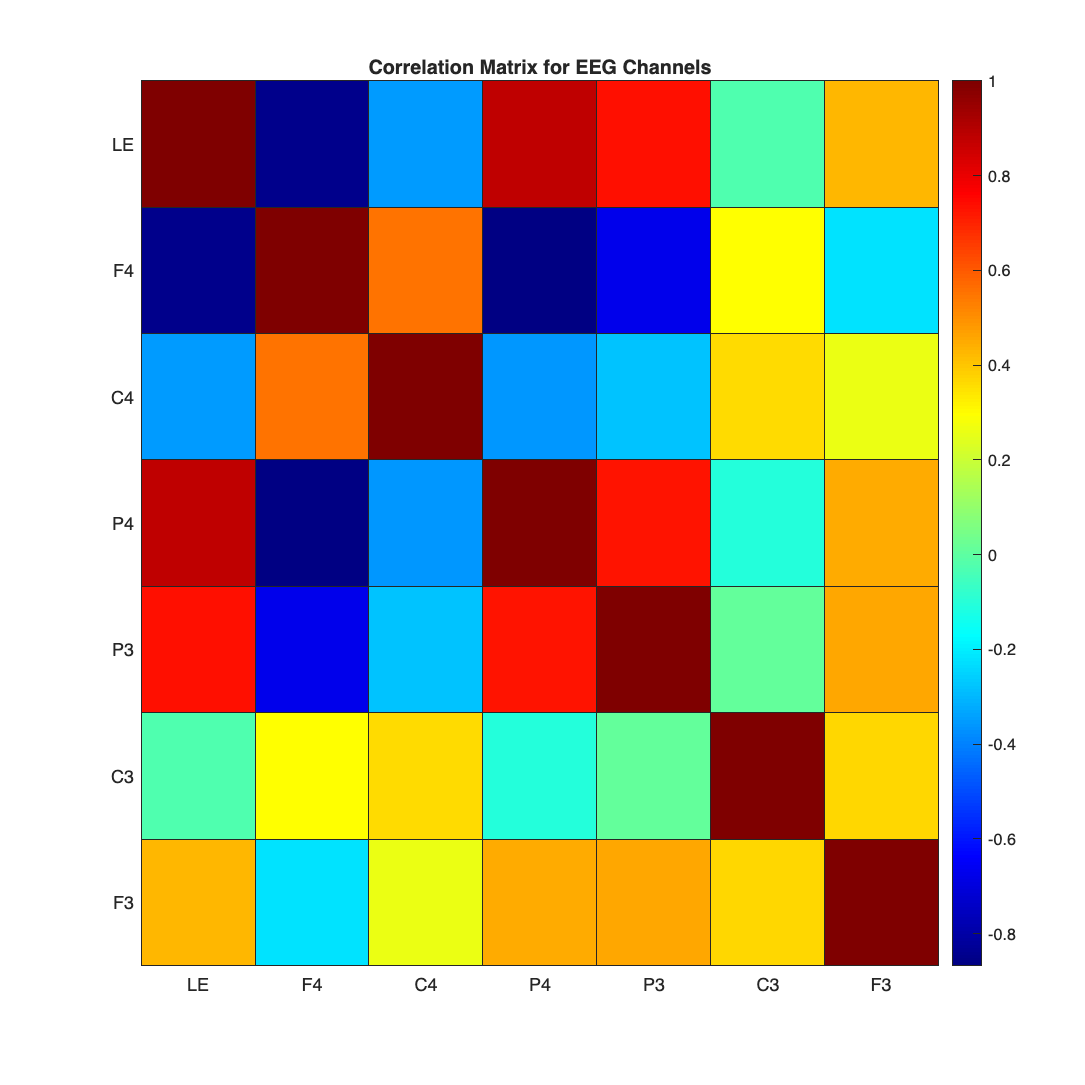


% Compute the correlation matrix
correlation_matrix = corr(eeg_channels);

% Plot correlation matrix as heatmap
figure('Name', 'EEG Correlation Matrix', 'Position', [100, 100, 800, 800]);
heatmap(["LE", "F4", "C4", "P4", "P3", "C3", "F3"], ...
        ["LE", "F4", "C4", "P4", "P3", "C3", "F3"], ...
        correlation_matrix, ...
        'Colormap', jet, ...
        'ColorbarVisible', 'on', ...
        'CellLabelColor', 'none'); % Optional to hide correlation labels
title('Correlation Matrix for EEG Channels');

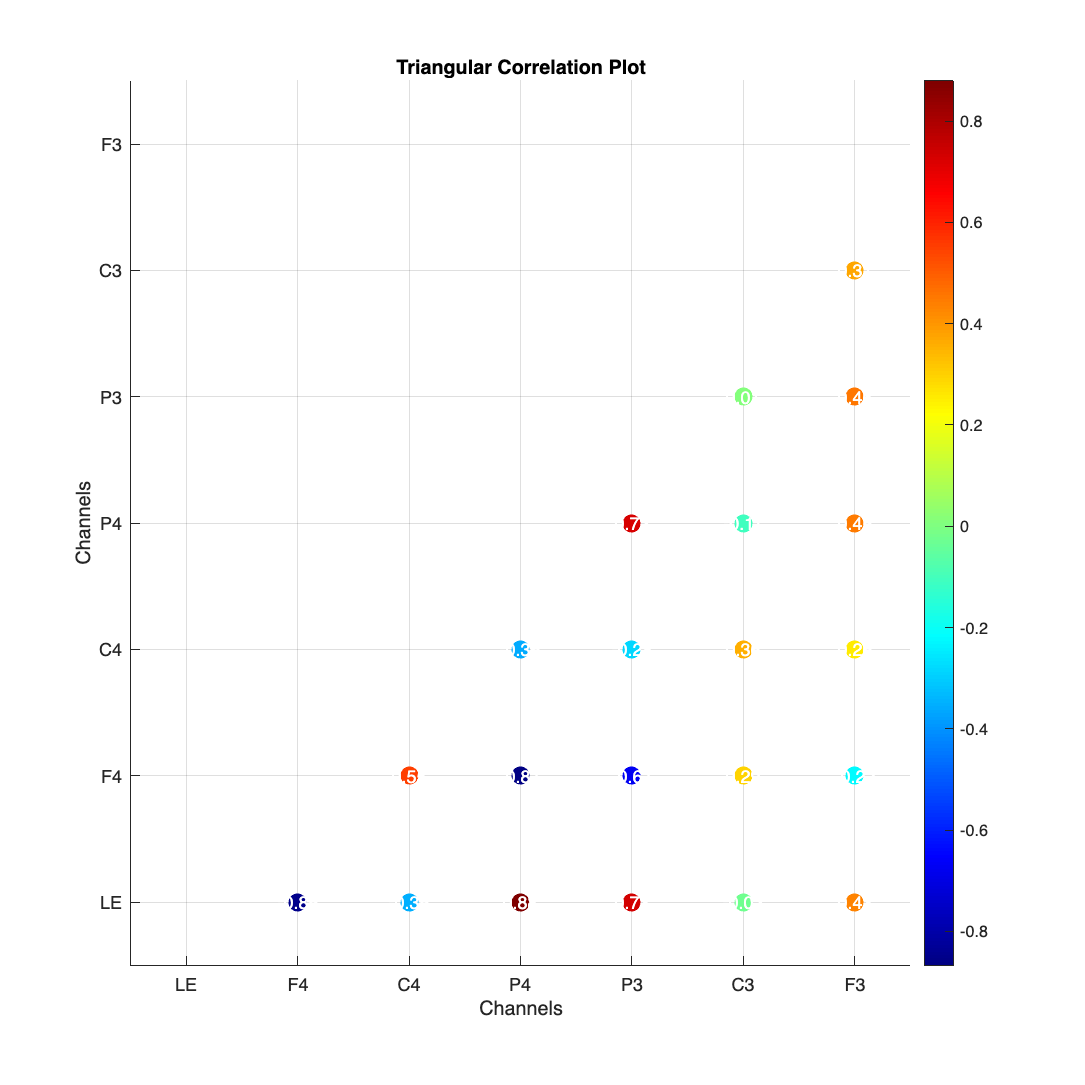


% Generate correlation plot
figure('Name', 'Triangular Correlation Plot', 'Position', [100, 100, 800, 800]);
hold on;
n_channels = size(correlation_matrix, 1);
for i = 1:n_channels
    for j = 1:i
        if i ~= j
            scatter(i, j, 100, correlation_matrix(i, j), 'filled');
            text(i, j, sprintf('%.2f', correlation_matrix(i, j)), ...
                'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'w');
        end
    end
end
colormap(jet);
colorbar;
xlim([0.5, n_channels + 0.5]);
ylim([0.5, n_channels + 0.5]);
xticks(1:n_channels);
yticks(1:n_channels);
xticklabels(["LE", "F4", "C4", "P4", "P3", "C3", "F3"]);
yticklabels(["LE", "F4", "C4", "P4", "P3", "C3", "F3"]);
xlabel('Channels');
ylabel('Channels');
title('Triangular Correlation Plot');
grid on;
hold off;

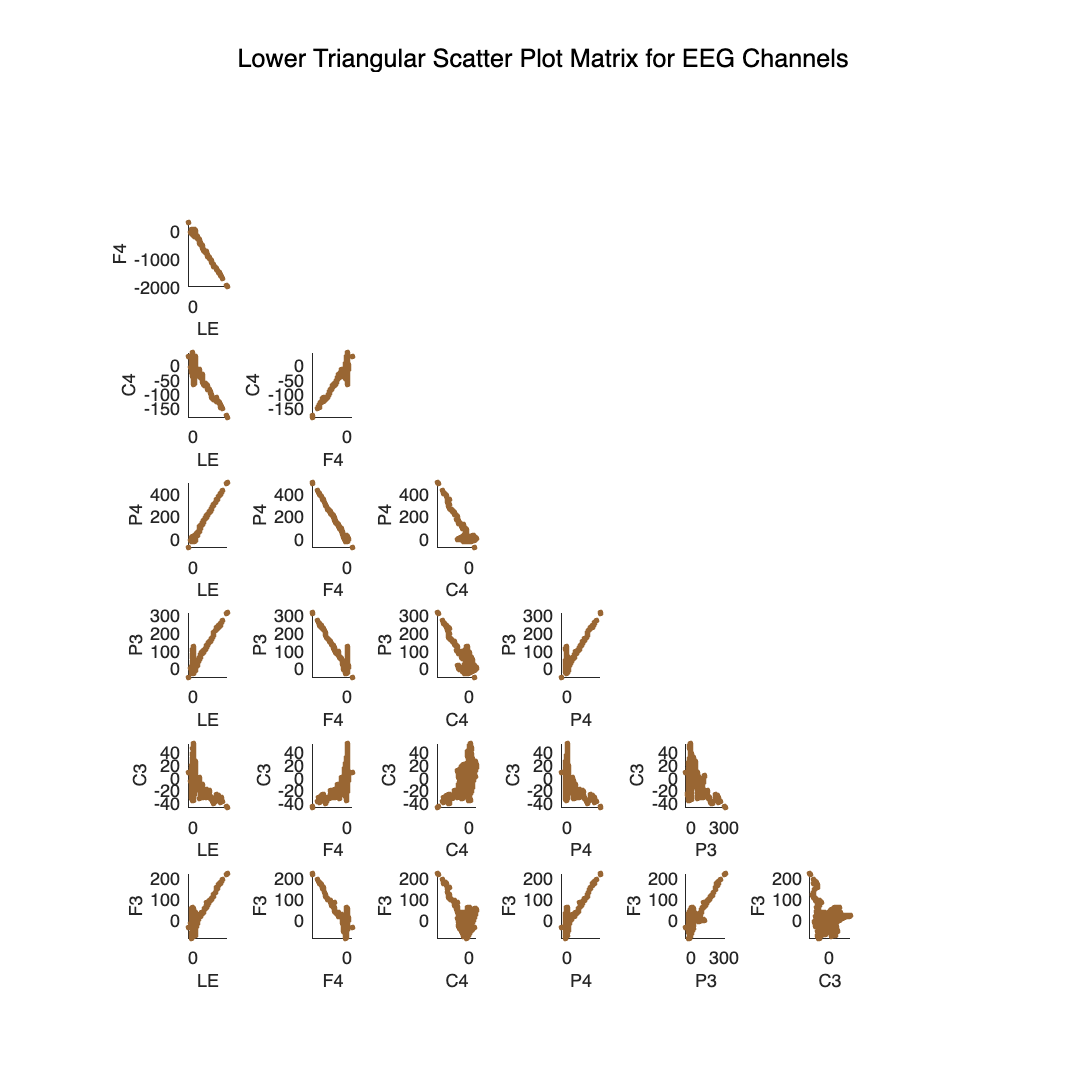

% Extract relevant variables from WaveFistRub1
eeg_channels = WFR5{:, ["LE", "F4", "C4", "P4", "P3", "C3", "F3"]};
channel_names = ["LE", "F4", "C4", "P4", "P3", "C3", "F3"];
num_channels = size(eeg_channels, 2);

% Create figure for scatter plot matrix
figure('Name', 'Scatter Plot Matrix for EEG-1 Channels', 'Position', [100, 100, 1000, 1000]);

for i = 2:num_channels
    for j = 1:i-1
        % Plot the scatter plot with brown dots
        subplot(num_channels, num_channels, (i-1) * num_channels + j);
        scatter(eeg_channels(:, j), eeg_channels(:, i), 10, [0.6, 0.4, 0.2], 'filled'); % Brown color for dots
        xlabel(channel_names(j), 'FontSize', 10);
        ylabel(channel_names(i), 'FontSize', 10);
        xlim([min(eeg_channels(:, j)) max(eeg_channels(:, j))]);
        ylim([min(eeg_channels(:, i)) max(eeg_channels(:, i))]);
    end
end

% Remove upper triangle subplots to create lower triangular matrix
for i = 1:num_channels
    for j = i:num_channels
        subplot(num_channels, num_channels, (i-1) * num_channels + j);
        axis off;
    end
end

% Title for the scatter plot matrix
sgtitle('Lower Triangular Scatter Plot Matrix for EEG Channels', 'FontSize', 14);


% Read additional data from another file
data = readtable("/Users/gayatrimalladi/Desktop/untitled folder/Prof_Mat_pre_stroke/WFR5.txt"); 

% Extract EEG channels and time from the new data
eeg_channels = data{:, {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}};
time = data{:, 'Time'};


% Extract EEG channels
eeg_channels = WFR5{:, ["LE", "F4", "C4", "P4", "P3", "C3", "F3"]};
% 1. Zero Crossing Rate
zero_crossing_rate = sum(diff(sign(eeg_channels)) ~= 0, 1) / size(eeg_channels, 1);
disp(zero_crossing_rate)

    0.0967    0.0422    0.0676    0.0857    0.0826    0.0901    0.0759




% 2. Skewness
skewness_val = skewness(eeg_channels, 0, 1);
disp(skewness_val)

   13.4122  -15.7337   -2.3623   15.0468    8.6439    0.1407    0.8971




% 3. Kurtosis
kurtosis_val = kurtosis(eeg_channels, 0, 1);
disp(kurtosis_val)

  260.5131  314.5997   23.7531  301.5552  130.5377    5.5233   22.2469



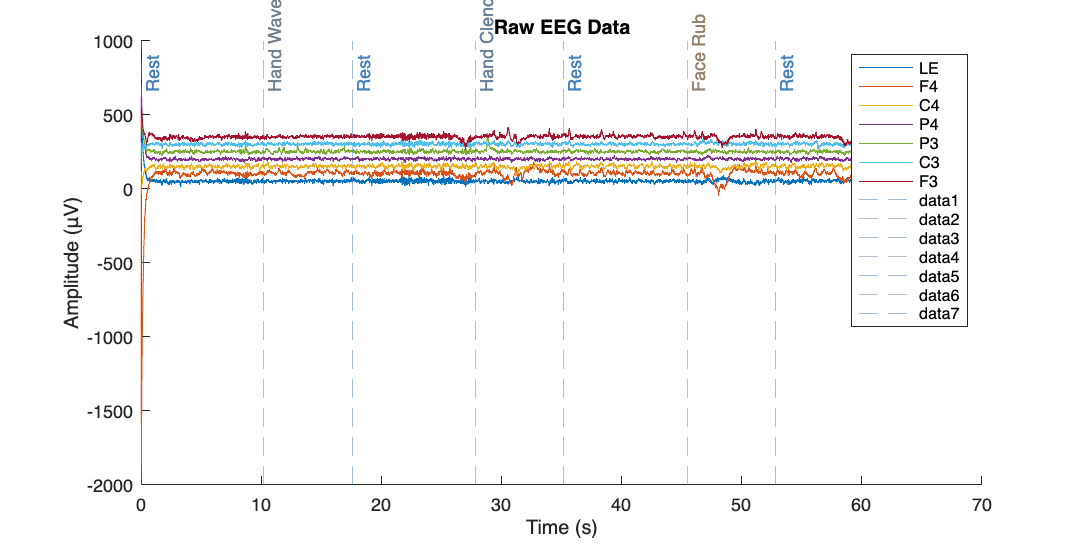

% Extract relevant data
time = data.Time; 
comments = data.Comments; 
eeg_channels = data{:, {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}}; % EEG channels
ch_names = {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}; % Channel names
sfreq = 300; % Sampling frequency
% Step 1: Parse comments and timestamps
comment_timestamps = [];
comment_names = {};
for i = 1:height(data)
    if ischar(data.Comments{i}) && ~isempty(strtrim(data.Comments{i}))
        comment_timestamps(end+1) = data.Time(i); % Add timestamp
        comment_names{end+1} = data.Comments{i}; % Add comment
    end
end
% Step 2: Generate a color for each comment
hash = @(str) mod(sum(double(str) .* (1:length(str))), 256); % Simple hash function
name_to_color = @(name) [hash(name)/255, 0.5, 1 - hash(name)/255]; % Generate RGB colors
% Step 3: Plot raw EEG data
figure('Name', 'Raw EEG Data', 'Position', [100, 100, 1000, 500]);
colors = lines(length(ch_names)); % Define colors for channels

hold on;
for i = 1:size(eeg_channels, 2)
    plot(time, eeg_channels(:, i) + i * 50, 'Color', colors(i, :), 'DisplayName', ch_names{i}); % Offset each channel for clarity
end
% Add vertical lines and labels for comments
for i = 1:length(comment_timestamps)
    comment_color = name_to_color(comment_names{i});
    xline(comment_timestamps(i), '--', 'Color', comment_color, 'Alpha', 0.5);
    text(comment_timestamps(i), max(max(eeg_channels)) + 100, comment_names{i}, ...
        'Rotation', 90, 'VerticalAlignment', 'top', 'Color', comment_color);
end

title('Raw EEG Data');
xlabel('Time (s)');
ylabel('Amplitude (μV)');
legend('show');
hold off;

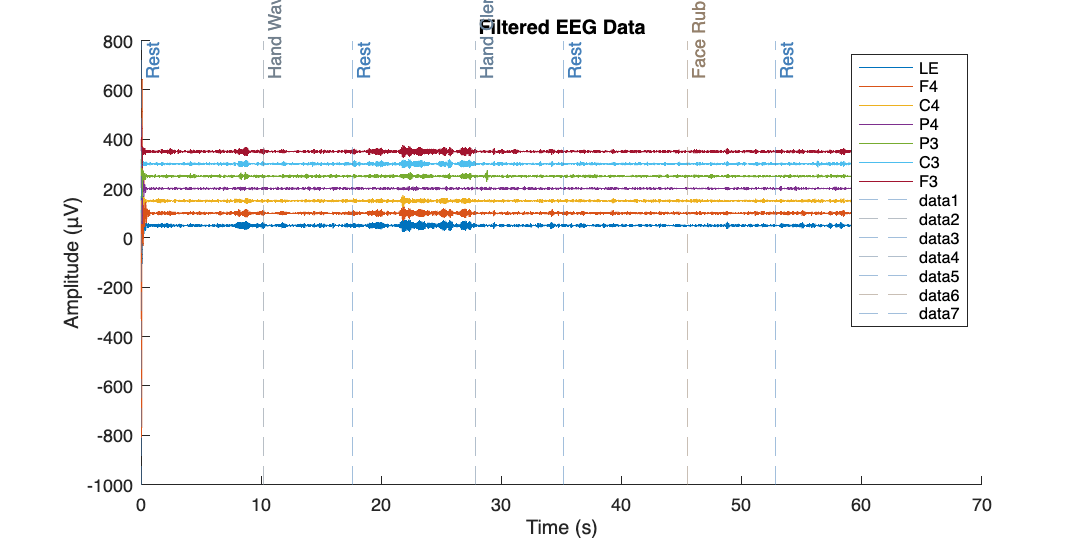

% Step 4: Apply filters (notch and bandpass)
notch_freqs = [50, 60];
for f = notch_freqs
    d = designfilt('bandstopiir', 'FilterOrder', 2, ...
        'HalfPowerFrequency1', f - 1, ...
        'HalfPowerFrequency2', f + 1, ...
        'SampleRate', sfreq);
    eeg_channels = filtfilt(d, eeg_channels); % Apply notch filter
end
% Bandpass filter
low_freq = 7; high_freq = 14;
[b, a] = butter(4, [low_freq high_freq] / (sfreq / 2), 'bandpass');
filtered_data = filtfilt(b, a, eeg_channels);
% Step 5: Plot filtered EEG data
figure('Name', 'Filtered EEG Data', 'Position', [100, 100, 1000, 500]);
hold on;
for i = 1:size(filtered_data, 2)
    plot(time, filtered_data(:, i) + i * 50, 'Color', colors(i, :), 'DisplayName', ch_names{i}); % Offset each channel
end
% Add vertical lines and labels for comments
for i = 1:length(comment_timestamps)
    comment_color = name_to_color(comment_names{i});
    xline(comment_timestamps(i), '--', 'Color', comment_color, 'Alpha', 0.5);
    text(comment_timestamps(i), max(max(filtered_data)) + 100, comment_names{i}, ...
        'Rotation', 90, 'VerticalAlignment', 'top', 'Color', comment_color);
end
title('Filtered EEG Data');
xlabel('Time (s)');
ylabel('Amplitude (μV)');
legend('show');
hold off;

% Step 6: Time-frequency analysis using wavelet transform
frequencies = 1:80; % Frequencies of interest
n_cycles = frequencies / 2; % Number of cycles in the wavelet
time_range = 1:length(time) / sfreq;
% Morlet wavelet analysis
[power_raw, ~] = cwt(eeg_channels(:, 1), sfreq, 'FrequencyLimits', [min(frequencies) max(frequencies)]); % Example on channel 1
[power_filtered, ~] = cwt(filtered_data(:, 1), sfreq, 'FrequencyLimits', [min(frequencies) max(frequencies)]); % Example on channel 1
% Plot time-frequency analysis for raw data
figure('Name', 'Time-Frequency Analysis (Raw)', 'Position', [100, 100, 1000, 500]);
